% Lab 3 Task 3
% Measure system gain at frequency f_sig

clear all;
ports = serialportlist;
pb = PyBench(ports(end)); % create a PyBench object

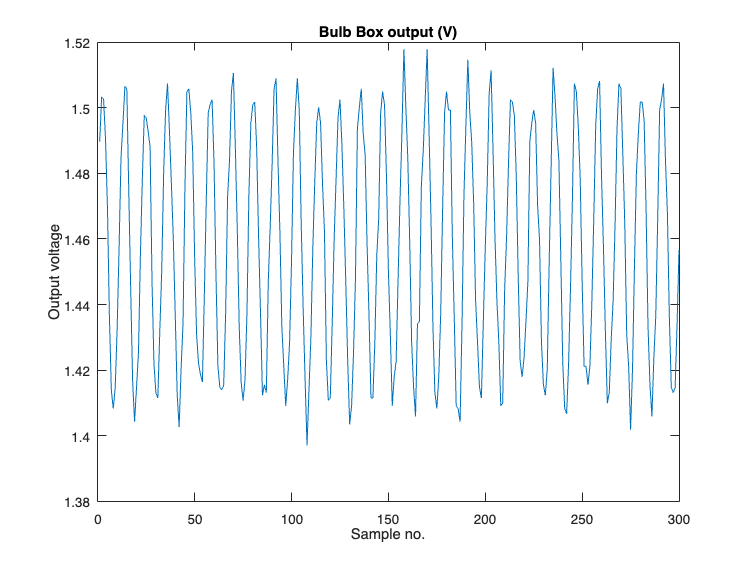


% Generate a sine wave at sig_freq Hz
max_x = 1.55;
min_x = 1.45;
f_sig = 9;
pb = pb.set_sig_freq(f_sig);
pb = pb.set_max_v(max_x);
pb = pb.set_min_v(min_x);
pb.sine();
pause(2);

% Capture output y(t)
pb = pb.set_samp_freq(100); % sample at 100Hz
N = 300; % no of samples to capture
y = pb.get_block(N);

% Plot signal
plot(y);
xlabel('Sample no.');
ylabel('Output voltage');
title('Bulb Box output (V)');


% Compute Gain
x_pk2pk = max_x - min_x;
y_pk2pk = max(y) - min(y);
G = y_pk2pk / x_pk2pk;
G_dB = 20 * log10(y_pk2pk / x_pk2pk)

G_dB = 1.6449